Patriks Raiss-Reiss Adaptronika 3. kurss 231REC051

Variants: 753

Basic scenario/map setup

clear all;

sampleRate = 10;
scenario = robotScenario(UpdateRate=sampleRate);

floorColor = [1 0 0.5];
addMesh(scenario, "Plane", Position=[4.5 2.5 0], Size=[9 5], Color=floorColor);

wallHeight = 1;
wallWidth = 0.05;
wallColor = [1 1 0.8157];

Add outer walls to the map

addMesh(scenario, "Box", Position=[0+wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 5-wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[9-wallWidth/2, 2.5, wallHeight/2], ...
    Size=[wallWidth, 5, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4.5, 0+wallWidth/2, wallHeight/2], ...
    Size=[9, wallWidth, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Add inner walls to the map

addMesh(scenario, "Box", Position=[1, 2, wallHeight/2], ...
    Size=[2, 4, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[4, 1.5, wallHeight/2], ...
    Size=[2, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6, 3.5, wallHeight/2], ...
    Size=[4, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[6.5, 2, wallHeight/2], ...
    Size=[1, 2, wallHeight], Color=wallColor, IsBinaryOccupied=true);
addMesh(scenario, "Box", Position=[7.5, 1.5, wallHeight/2], ...
    Size=[1, 1, wallHeight], Color=wallColor, IsBinaryOccupied=true);

Visualize the map

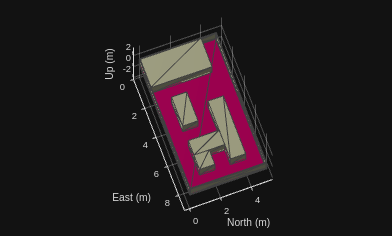

show3D(scenario);
lightangle(-45, 30);
view(70, 70);
grid on;

Setup the basic path

startPosition = [1 4.5];
chargingPosition = [8 0.5];

wPts = [[startPosition 0.1]; ...
    2.5 5 0.1; ...
    2.5 1 0.1; ...
    8.5 1 0.1];

toa = [0 1 2 3];
traj = waypointTrajectory(Waypoints=wPts, ...
    TimeOfArrival=toa, ReferenceFrame="ENU", ...
    SampleRate=sampleRate);

[pos, orient, vel, acc, angvel] = traj.lookupPose(0:1/sampleRate:10);

Setup the charging station

addMesh(scenario, "Plane", Position=[8 0.5 0.05], Size=[1, 1], Color=[0 1 0]);

chargeStation = robotPlatform("chargeStation", scenario, InitialBasePosition=[8.5 0.5 0]);
chargeStation.updateMesh("Cuboid", Size=[0.4 0.8 0.7], Color=[0 0.8 0]);

Define and setup te robot

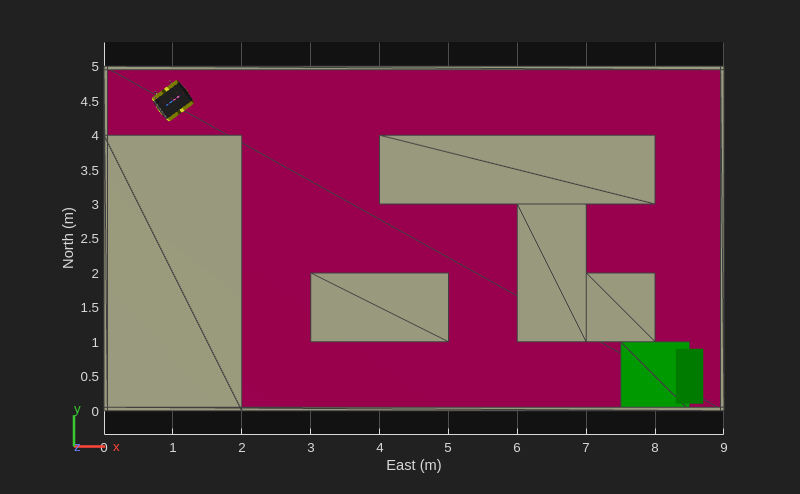

platform = robotPlatform("rst", scenario, ...
    RigidBodyTree=loadrobot("clearpathJackal"), ...
    InitialBasePosition=pos(1, :), InitialBaseOrientation=compact(orient(1)));

show3D(scenario);
lightangle(-45, 30);
view(0, 90);
grid on;

Setup the ultrasonic sensor

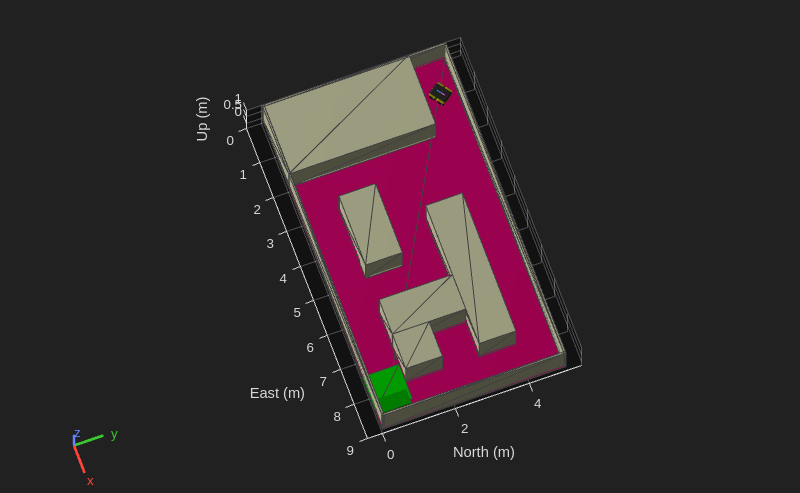

chargingStationProfile = struct("Length", 0.4, "Width", 0.8, "Height", 0.7, "OriginOffset", [0 0 0]);

ultraSonicSensorModel = ultrasonicDetectionGenerator(MountingLocation=[0 0 0], ...
    DetectionRange=[0.03 0.04 5], FieldOfView=[70, 35], Profiles=chargingStationProfile);

ult = robotSensor("UltraSonic", platform, CustomUltrasonicSensor(ultraSonicSensorModel), ...
    MountingLocation=[0.5 0 0.05]);

figure(1);
ax = show3D(scenario);
lightangle(-45, 30);
view(70, 70);
grid on;

Setup the movement logic

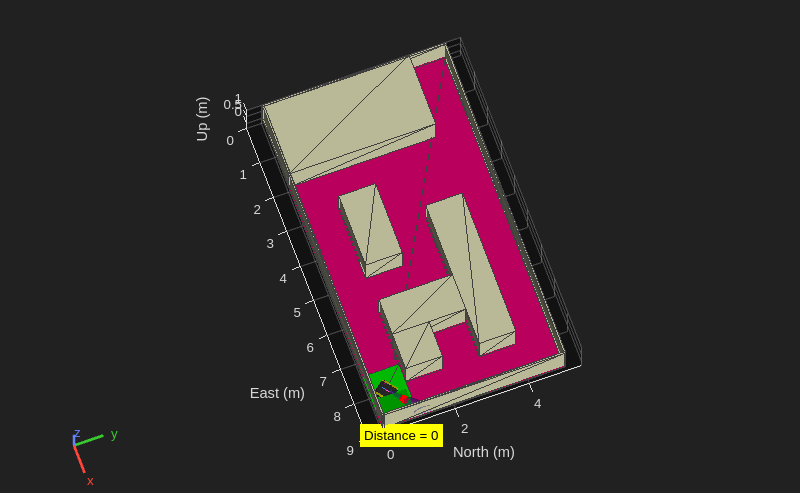

isCharging = false;
i = 1;

setup(scenario);

while ~isCharging
    [isUpdated, t, det, isValid] = read(ult);

    figure(1);
    show3D(scenario);
    view(70, 70);
    light;
    grid on;

    pose = platform.read();
    rotAngle = quat2eul(pose(10:13));
    hold on;

    if ~isempty(det)
        distance = det{1}.Measurement;

        exampleHelperPlotDetectionPoint(scenario, ...
            det{1}.ObjectAttributes{1}.PointOnTarget, ult.Name, pose);

        displayText = ['Distance = ', num2str(distance)];
    else
        distance = inf;
        displayText = 'No object detected!';
    end

    exampleHelperPlotFOVCylinder(pose, ultraSonicSensorModel.DetectionRange(3));
    hold off;

    if distance <= 0.2
        currentMotion = lastMotion;
        currentMotion(1) = currentMotion(1) + 0.01;

        move(platform, "base", currentMotion);
        lastMotion = currentMotion;
        displaytext = ['Detected charger! Distance = ', num2str(distance)];

        if distance <= 0.05
            displaytext = ['Charging! Distance = ', num2str(distance)];
            isCharging = true;
        end
    else
        if i<=length(pos)
            motion = [pos(i,:), vel(i,:), acc(i,:), compact(orient(i)), angvel(i,:)];
            move(platform, "base", motion);
            lastMotion = motion;
            i=i+1;
        end
    end

    t = text(9, -0.5, displayText, "BackgroundColor", "yellow");
    t(1).Color = "black";
    t(1).FontSize = 10;

    advance(scenario);

    updateSensors(scenario);
end